%%%% ============= Node Wise Dissimilar Load Profile: PCA Spatial Data Reconstruction ============= %%%%

clear all
close all
clc

file='Data.xlsx';

% =================  Bus power data of IEEE 123 bus ================= %
% data1=xlsread(file,1); % Bus power data
% bus=data1(:,1);
% phA_kw=data1(:,2);
% phA_kVAR=data1(:,3);
% phB_kw=data1(:,4);
% phB_kVAR=data1(:,5);
% phC_kw=data1(:,6);
% phC_kVAR=data1(:,7);
% T_kw=data1(:,8);
% T_kVAR=data1(:,9);
% Nbus=max(bus);

data1=xlsread(file,8); % Bus power data
bus=data1(:,1);
T_kw=data1(:,2);
T_kVAR=data1(:,3);
Nbus=max(bus);

% ============ Sample load profile generation: 1-min ============== %
% T=96; 
T=24*60;

% % ==== Dissimilar Load Profile ====
data2=xlsread(file,5);
trainpu=data2(2:1441,2:126);
trainpu(:,127:129) = 0

trainpu =     1.1601    1.2963    0.8345    0.9911    1.2374    1.2481    0.8765    1.0056    1.0443    1.1550    1.0422    1.1757    1.2934    0.9926    0.9022    1.1814    1.1924    1.2117    0.8431    0.9810    0.9071    1.0720    1.0977    0.8288    1.1259    0.9954    0.9480    1.0190    1.0475    0.9498    1.0449    0.8848    1.2910    0.9482    0.8399    1.0682    1.2970    0.8249    1.2550    1.0240    1.1521    1.1365    1.1009    0.8528    0.9662    1.1791    1.1237    1.0466    1.2159    1.2542
    0.9734    1.0279    0.8834    1.1465    1.0301    1.1708    1.2145    1.2082    1.1488    1.2712    1.0348    0.8302    1.1061    1.2283    1.0569    1.1614    0.8900    1.2486    1.2287    0.9623    1.1330    0.8161    1.2951    1.1397    0.8761    1.0304    0.8246    1.1734    1.1759    0.9130    1.1310    1.2548    1.2944    0.8806    1.0873    1.2676    1.2870    1.1999    0.9976    1.0746    1.0748    1.2204    1.1641    0.9729    1.0639    1.0375    0.9576    1.0441    1.127

size(trainpu)

ans =         1440         129


% trainpu=data2(2:97,2:126);
% plot(data2(2:1441,1),trainpu)
% plot(data2(2:97,1),trainpu)
% L=zeros(T,Nbus);
% for n=1:Nbus
%     for t=1:T
%         L(t,n)=(1.3-0.8)*rand+0.8;
%     end
% end
% plot(L)


% % Test load profile 15-min
data3=xlsread(file,6);
testpu=data2(2:97,2:126);
testpu(:,127:129) = 0

testpu =     1.1601    1.2963    0.8345    0.9911    1.2374    1.2481    0.8765    1.0056    1.0443    1.1550    1.0422    1.1757    1.2934    0.9926    0.9022    1.1814    1.1924    1.2117    0.8431    0.9810    0.9071    1.0720    1.0977    0.8288    1.1259    0.9954    0.9480    1.0190    1.0475    0.9498    1.0449    0.8848    1.2910    0.9482    0.8399    1.0682    1.2970    0.8249    1.2550    1.0240    1.1521    1.1365    1.1009    0.8528    0.9662    1.1791    1.1237    1.0466    1.2159    1.2542
    0.9734    1.0279    0.8834    1.1465    1.0301    1.1708    1.2145    1.2082    1.1488    1.2712    1.0348    0.8302    1.1061    1.2283    1.0569    1.1614    0.8900    1.2486    1.2287    0.9623    1.1330    0.8161    1.2951    1.1397    0.8761    1.0304    0.8246    1.1734    1.1759    0.9130    1.1310    1.2548    1.2944    0.8806    1.0873    1.2676    1.2870    1.1999    0.9976    1.0746    1.0748    1.2204    1.1641    0.9729    1.0639    1.0375    0.9576    1.0441    1.1274

% figure
% plot(data3(2:97,1),testpu)
T1=24*60/15;
% for n=1:Nbus
% for t=1:T1
%     Lt(t,n)=(1.3-0.8)*rand+0.8;
% end
% end
%training load profile plot
load_profile = xlsread(file,5)

load_profile = 1.0e+03 *

       NaN    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490
    0.0010    0.0012    0.0013    0.0008    0.0010    0.0012    0.0012    0.0009    0.0010    0.0010    0.0012    0.0010    0.0012    0.0013    0.0010    0.0009    0.0012    0.0012    0.0012    0.0008    0.0010    0.0009    0.0011    0.0011    0.0008    0.0011    0.0010    0.0009    0.0010    0.0010    0.0009    0.0010    0.0009    0.0013    0.0009    0.0008    0.0011    0.0013    0.0008    0.0013    0.0010    0.0012    0.0011    0.0011    0.0009    0.0010    0.0012   

train_profile = load_profile(2:end,2:end)

train_profile =     1.1601    1.2963    0.8345    0.9911    1.2374    1.2481    0.8765    1.0056    1.0443    1.1550    1.0422    1.1757    1.2934    0.9926    0.9022    1.1814    1.1924    1.2117    0.8431    0.9810    0.9071    1.0720    1.0977    0.8288    1.1259    0.9954    0.9480    1.0190    1.0475    0.9498    1.0449    0.8848    1.2910    0.9482    0.8399    1.0682    1.2970    0.8249    1.2550    1.0240    1.1521    1.1365    1.1009    0.8528    0.9662    1.1791    1.1237    1.0466    1.2159    1.2542
    0.9734    1.0279    0.8834    1.1465    1.0301    1.1708    1.2145    1.2082    1.1488    1.2712    1.0348    0.8302    1.1061    1.2283    1.0569    1.1614    0.8900    1.2486    1.2287    0.9623    1.1330    0.8161    1.2951    1.1397    0.8761    1.0304    0.8246    1.1734    1.1759    0.9130    1.1310    1.2548    1.2944    0.8806    1.0873    1.2676    1.2870    1.1999    0.9976    1.0746    1.0748    1.2204    1.1641    0.9729    1.0639    1.0375    0.9576    1.0441   

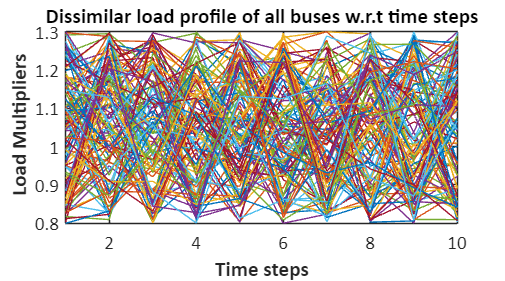

figure('Renderer', 'painters', 'Position', [10 10 900 500])
plot(train_profile)
title('Dissimilar load profile of all buses w.r.t time steps')
xlabel('Time steps','FontWeight', 'bold')
ylabel(' Load Multipliers','FontWeight', 'bold')
xlim([1 10])
set(gca,'fontsize',16,'Fontname','Calibri','GridAlpha',0.5)
saveas(gca,'dissimilar_load_profile.svg')

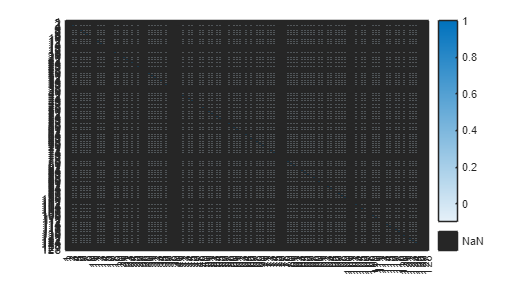



% % ======== Offline calculation of PCA parameters: Bus wise ========== %
P_L_demo=zeros(Nbus,T);
for n=1:Nbus
    for t=1:T
        P_L_demo(n,t)=trainpu(t,n)*T_kw(n,1);
    end
end
size_P=size(P_L_demo);

% Mean vector calculation
P_avg=zeros(Nbus,1);
for n=1:Nbus
    S=0;
    for t=1:T
        S=S+P_L_demo(n,t);
    end
    P_avg(n,1)=(1/T)*S;
end

% Correlation Matrix Calculation
Corr_P_L=zeros(Nbus,Nbus);
for m=1:Nbus
    for n=1:Nbus
        S1=0; S2=0; S3=0;
        for t=1:T
            S1=S1+(P_L_demo(m,t)-P_avg(m,1))*(P_L_demo(n,t)-P_avg(n,1));
            S2=S2+power((P_L_demo(m,t)-P_avg(m,1)),2);
            S3=S3+power((P_L_demo(n,t)-P_avg(n,1)),2);
        end
        Corr_P_L(m,n)=S1/sqrt(S2*S3);
    end
end
heatmap(Corr_P_L)



% % Covariance matrix calculation
P_L_norm=P_L_demo-P_avg;
%Cov_P_L=cov(P_L_norm)
Cov_P_L=zeros(Nbus,Nbus);
for m=1:Nbus
    for n=1:Nbus
        S=0;
        for t=1:T
            S=S+(P_L_demo(m,t)-P_avg(m,1))*(P_L_demo(n,t)-P_avg(n,1));
        end
        Cov_P_L(m,n)=(1/T)*S;
    end
end
size_cov=size(Cov_P_L);
Cov_P_L_pu=Cov_P_L/1000;
% 
% % Eigen values (D) and vectors (V) of covariance matrix
[V,D]=eig(Cov_P_L);

% Sort eigen vectors
non_sortV=V;
colSums = sum(V);
[sumsorted , sortedIndices] = sort(colSums, 'descend');  % Sort indices in descending order
sortedV = V(:, sortedIndices);  % Rearrange columns based on sorted indices
% 
% %%%%%%%%%%%%%%% Online data collection and data recovery %%%%%%%%%%%%%
itrmax=50;
for itr=1:itrmax
    Ttest=1; % Testing time interval
    L=50; % Total number of data collecting nodes
    
    
    for n=1:Nbus
        for t=1:T1
            S_L_test(n,t)=testpu(t,n)*T_kw(n,1);
        end
    end
    % figure
    % plot(S_L_test(:,1))
    
    
    % UL=sortedV(:,1:L);
    UL=sortedV(:,1);
    %S_L=zeros(Nbus,1);
    S_L = P_avg% Original power at collected nodes
    % n_L=(randperm(Nbus, L))'; % Index of selected node 
    
    
    % Identify nodes having loads
    k=1;
    for n=1:Nbus
        if T_kw(n,1)~=0
            n_load(k,1)=n;
            k=k+1;
        end
    end
    
    i_L=(randperm(length(n_load), L))'; % Index of selected item from n_load
    
    % Selected Node and their actual measurement
    n_L=zeros(L,1);
    for l=1:L
        n_L(l,1)=n_load(i_L(l,1),1);
    end

    for l=1:L
        S_L(n_L(l,1),1,1)=testpu(Ttest,n_L(l,1))*T_kw(n_L(l,1),1);
    end
    S_L = S_L - P_avg;
    % Recovered data
    S_L_rec=P_avg+UL*UL'*S_L;
    
    % Integrated normalized absolute error (INAE) and Data Plot
    S_test_tot=zeros(1,T1);
    for t=1:T1
        for n=1:Nbus
            S_test_tot(1,t)=S_test_tot(1,t)+S_L_test(n,t);
        end
    end
    
    
    S_rec_tot=0;
    for n=1:Nbus
        S_rec_tot=S_rec_tot+abs(S_L_test(n,Ttest)-S_L_rec(n,1));
    end
    INAE=S_rec_tot/S_test_tot(1,Ttest)
    
    Error(itr,1)=INAE*100;
end

S_L =          0
         0
   13.9568
    6.9911
         0
   13.9613
    7.0436
   13.9236
    6.9870
         0


INAE = 0.1131

S_L =          0
         0
   13.9568
    6.9911
         0
   13.9613
    7.0436
   13.9236
    6.9870
         0


INAE = 0.1139

S_L =          0
         0
   13.9568
    6.9911
         0
   13.9613
    7.0436
   13.9236
    6.9870
         0


INAE = 0.1128

S_L =          0
         0
   13.9568
    6.9911
         0
   13.9613
    7.0436
   13.9236
    6.9870
         0


INAE = 0.1131

S_L =          0
         0
   13.9568
    6.9911
         0
   13.9613
    7.0436
   13.9236
    6.9870
         0


INAE = 0.1127

S_L =          0
         0
   13.9568
    6.9911
         0
   13.9613
    7.0436
   13.9236
    6.9870
         0


INAE = 0.1134

S_L =          0
         0
   13.9568
    6.9911
         0
   13.9613
    7.0436
   13.9236
    6.9870
         0


INAE = 0.1131

S_L =          0
         0
   13.9568
    6.9911
         0
   13.9613
    7.0436
   13.9236
    6.9870
         0


INAE = 0.1138

S_L =          0
         0
   13.9568
    6.9911
         0
   13.9613
    7.0436
   13.9236
    6.9870
         0


INAE = 0.1130

S_L =          0
         0
   13.9568
    6.9911
         0
   13.9613
    7.0436
   13.9236
    6.9870
         0


INAE = 0.1140

S_L =          0
         0
   13.9568
    6.9911
         0
   13.9613
    7.0436
   13.9236
    6.9870
         0


INAE = 0.1128

S_L =          0
         0
   13.9568
    6.9911
         0
   13.9613
    7.0436
   13.9236
    6.9870
         0


INAE = 0.1132

S_L =          0
         0
   13.9568
    6.9911
         0
   13.9613
    7.0436
   13.9236
    6.9870
         0


INAE = 0.1129

S_L =          0
         0
   13.9568
    6.9911
         0
   13.9613
    7.0436
   13.9236
    6.9870
         0


INAE = 0.1135

S_L =          0
         0
   13.9568
    6.9911
         0
   13.9613
    7.0436
   13.9236
    6.9870
         0


INAE = 0.1133

S_L =          0
         0
   13.9568
    6.9911
         0
   13.9613
    7.0436
   13.9236
    6.9870
         0


INAE = 0.1138

S_L =          0
         0
   13.9568
    6.9911
         0
   13.9613
    7.0436
   13.9236
    6.9870
         0


INAE = 0.1130

S_L =          0
         0
   13.9568
    6.9911
         0
   13.9613
    7.0436
   13.9236
    6.9870
         0


INAE = 0.1129

S_L =          0
         0
   13.9568
    6.9911
         0
   13.9613
    7.0436
   13.9236
    6.9870
         0


INAE = 0.1129

S_L =          0
         0
   13.9568
    6.9911
         0
   13.9613
    7.0436
   13.9236
    6.9870
         0


INAE = 0.1128

S_L =          0
         0
   13.9568
    6.9911
         0
   13.9613
    7.0436
   13.9236
    6.9870
         0


INAE = 0.1130

S_L =          0
         0
   13.9568
    6.9911
         0
   13.9613
    7.0436
   13.9236
    6.9870
         0


INAE = 0.1128

S_L =          0
         0
   13.9568
    6.9911
         0
   13.9613
    7.0436
   13.9236
    6.9870
         0


INAE = 0.1132

S_L =          0
         0
   13.9568
    6.9911
         0
   13.9613
    7.0436
   13.9236
    6.9870
         0


INAE = 0.1130

S_L =          0
         0
   13.9568
    6.9911
         0
   13.9613
    7.0436
   13.9236
    6.9870
         0


INAE = 0.1129

S_L =          0
         0
   13.9568
    6.9911
         0
   13.9613
    7.0436
   13.9236
    6.9870
         0


INAE = 0.1128

S_L =          0
         0
   13.9568
    6.9911
         0
   13.9613
    7.0436
   13.9236
    6.9870
         0


INAE = 0.1127

S_L =          0
         0
   13.9568
    6.9911
         0
   13.9613
    7.0436
   13.9236
    6.9870
         0


INAE = 0.1129

S_L =          0
         0
   13.9568
    6.9911
         0
   13.9613
    7.0436
   13.9236
    6.9870
         0


INAE = 0.1134

S_L =          0
         0
   13.9568
    6.9911
         0
   13.9613
    7.0436
   13.9236
    6.9870
         0


INAE = 0.1133

S_L =          0
         0
   13.9568
    6.9911
         0
   13.9613
    7.0436
   13.9236
    6.9870
         0


INAE = 0.1128

S_L =          0
         0
   13.9568
    6.9911
         0
   13.9613
    7.0436
   13.9236
    6.9870
         0


INAE = 0.1130

S_L =          0
         0
   13.9568
    6.9911
         0
   13.9613
    7.0436
   13.9236
    6.9870
         0


INAE = 0.1132

S_L =          0
         0
   13.9568
    6.9911
         0
   13.9613
    7.0436
   13.9236
    6.9870
         0


INAE = 0.1130

S_L =          0
         0
   13.9568
    6.9911
         0
   13.9613
    7.0436
   13.9236
    6.9870
         0


INAE = 0.1130

S_L =          0
         0
   13.9568
    6.9911
         0
   13.9613
    7.0436
   13.9236
    6.9870
         0


INAE = 0.1128

S_L =          0
         0
   13.9568
    6.9911
         0
   13.9613
    7.0436
   13.9236
    6.9870
         0


INAE = 0.1128

S_L =          0
         0
   13.9568
    6.9911
         0
   13.9613
    7.0436
   13.9236
    6.9870
         0


INAE = 0.1131

S_L =          0
         0
   13.9568
    6.9911
         0
   13.9613
    7.0436
   13.9236
    6.9870
         0


INAE = 0.1130

S_L =          0
         0
   13.9568
    6.9911
         0
   13.9613
    7.0436
   13.9236
    6.9870
         0


INAE = 0.1128

S_L =          0
         0
   13.9568
    6.9911
         0
   13.9613
    7.0436
   13.9236
    6.9870
         0


INAE = 0.1127

S_L =          0
         0
   13.9568
    6.9911
         0
   13.9613
    7.0436
   13.9236
    6.9870
         0


INAE = 0.1127

S_L =          0
         0
   13.9568
    6.9911
         0
   13.9613
    7.0436
   13.9236
    6.9870
         0


INAE = 0.1135

S_L =          0
         0
   13.9568
    6.9911
         0
   13.9613
    7.0436
   13.9236
    6.9870
         0


INAE = 0.1129

S_L =          0
         0
   13.9568
    6.9911
         0
   13.9613
    7.0436
   13.9236
    6.9870
         0


INAE = 0.1137

S_L = 128×1
         0
         0
   13.9568
    6.9911
         0
   13.9613
    7.0436
   13.9236
    6.9870
         0


INAE = 0.1130

S_L = 128×1
         0
         0
   13.9568
    6.9911
         0
   13.9613
    7.0436
   13.9236
    6.9870
         0


INAE = 0.1130

S_L = 128×1
         0
         0
   13.9568
    6.9911
         0
   13.9613
    7.0436
   13.9236
    6.9870
         0


INAE = 0.1132

S_L = 128×1
         0
         0
   13.9568
    6.9911
         0
   13.9613
    7.0436
   13.9236
    6.9870
         0


INAE = 0.1128

S_L = 128×1
         0
         0
   13.9568
    6.9911
         0
   13.9613
    7.0436
   13.9236
    6.9870
         0


INAE = 0.1128


figure
T=1:Nbus;
xlim([1 128])
p=plot(1:128,[S_L_test(:,Ttest),S_L_rec(:,1)],'LineWidth',1)

p =   2×1 Line array:

  Line
  Line


legend(["Original" "Reconstruct"],'Location','northwest')
p(1).Marker = 'o';
p(2).Marker = '*';
title('Reconstructed power data for dissimilar load profile')
ylabel('Power (kW)')
xlabel('Bus number')
ax = gca

ax =   Axes (Reconstructed power data for dissimilar load profile) with properties:

             XLim: [0 140]
             YLim: [-10 90]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


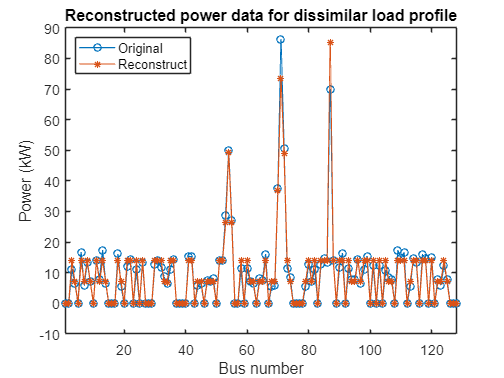

ax.FontSize = 12; 
xlim([1 128])

ax =   Axes (Reconstructed power data for dissimilar load profile) with properties:

             XLim: [1 128]
             YLim: [-10 90]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


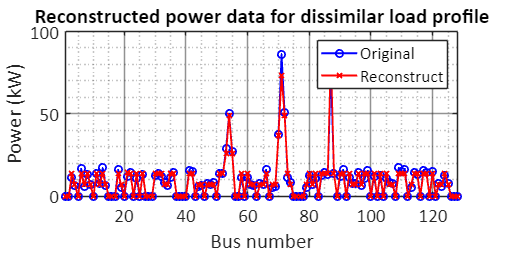


mplot(1:128,[S_L_test(:,Ttest)],1:128, [S_L_rec(:,1)])